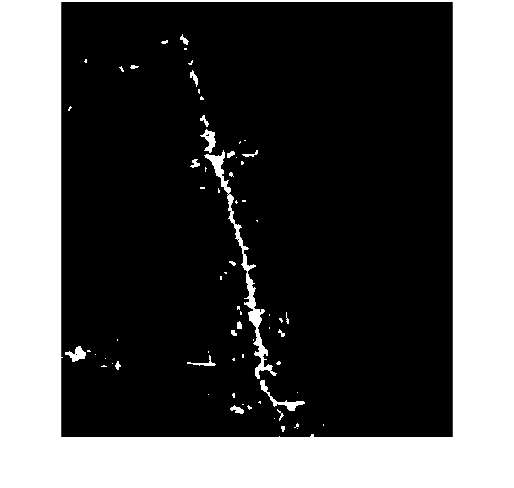

M = 800; N = 720;
image = zeros(5, M, N, 3); %instantiate image array
%get all images 
image(1,:,:,:) = imread("imageSeries1_year2000.jpg");
image(2,:,:,:) = imread("imageSeries1_year2004.jpg");
image(3,:,:,:) = imread("imageSeries1_year2008.jpg");
image(4,:,:,:) = imread("imageSeries1_year2012.jpg");
image(5,:,:,:) = imread("imageSeries1_year2016.jpg");
image = uint8(image);
area = getArea(image(1,:,:,:)); %area (km) same for all images

BW = zeros(5, M, N); %instantite BW image array
deforestPercent = zeros(1, 5);
deforestArea = zeros(1, 5);
for i = 1:5
    currentRGBImage = squeeze(image(i,:,:,:));
    BW(i, :, :) = getMask(currentRGBImage);
    
    numWhite = nnz(BW(i,:,:));% # white pixels
    numTotal = numel(BW(i,:,:)); % # of total pixels

    deforestPercent(i) = numWhite / numTotal; %percent deforestation of each image
    deforestArea(i) = deforestPercent(i) * area; %deforested area of each image
end
imshow(squeeze(BW(1,:,:)))

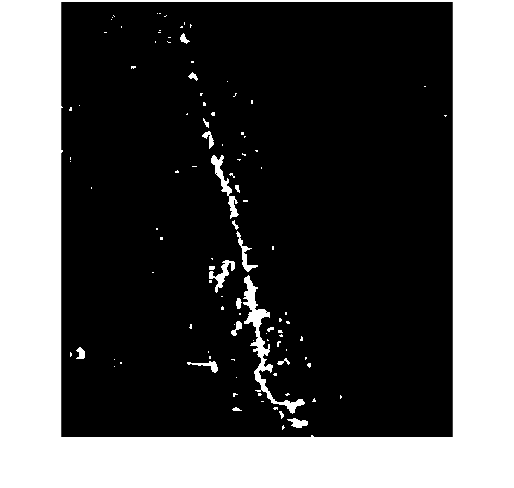

imshow(squeeze(BW(2,:,:)))

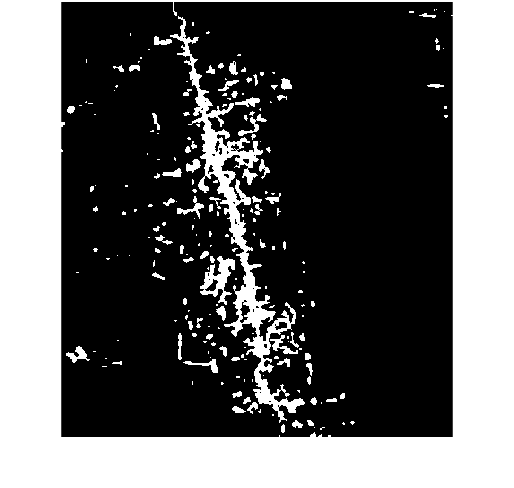

imshow(squeeze(BW(3,:,:)))

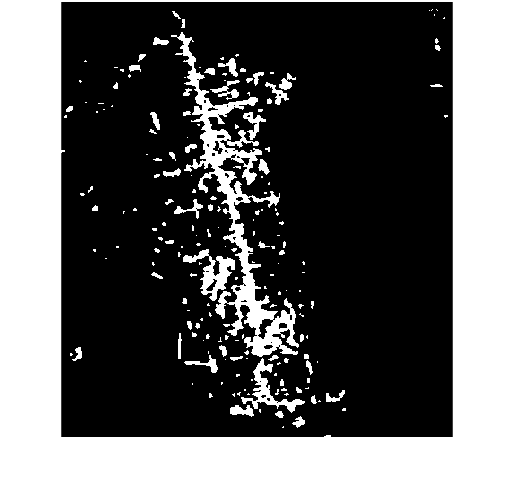

imshow(squeeze(BW(4,:,:)))

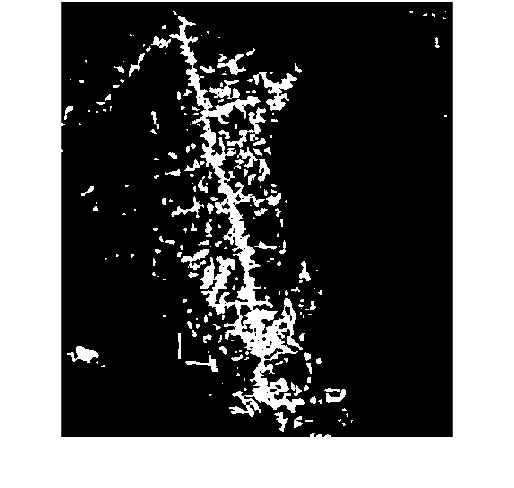

imshow(squeeze(BW(5,:,:)))

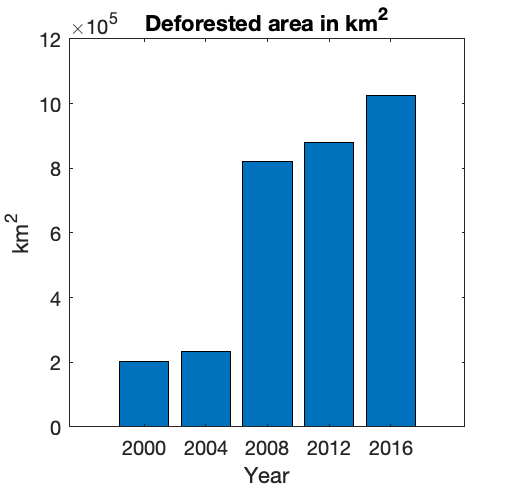


years = 2000:4:2016;
bar(years, deforestArea);
title("Deforested area in km^2")
xlabel("Year")
ylabel("km^2")



% year2000 = imread("imageSeries1_year2000.jpg");
% imshow(image(1))
% [BW2000, maskedRGBImage] = getMask(year2000);
% imshow(BW2000);
% imshow(maskedRGBImage);
% numTotal = numel(BW);
% numWhite = nnz(BW); %white is deforestation
% percentDeforested = numWhite/numTota
% 

%totalArea = getArea(year2000);
%deforestedArea = percentDeforested*totalArea;

%gray = im2gray(year2000);
% grayAdjust = imadjust(gray);
% imshow(grayAdjust)
% imshow(gray)
% imhist(grayAdjust)
% imhist(gray)
